h = 1/60;

N = 60 * 60; %count of instances observed, total time: N * h seconds.

m = 2; k = 0.8; r = 0.5; rho = 10; g = 9.82; %consts
consts = [m, k, r, rho, g];

phi = 360; %wave frequency => wave speed
A = 2/10; %amplitude
wavefunc = @(x,t)A * sind(phi * (x + h*t)) + 3;

p0 = 1; theta0 = 0; dL0 = 2; v0 = [0 0]; %variables
originalvals = [p0, theta0, dL0, v0]; %

buoypos = real(recursive(consts, wavefunc, originalvals, h, N)'); %(2 dim, t * time)

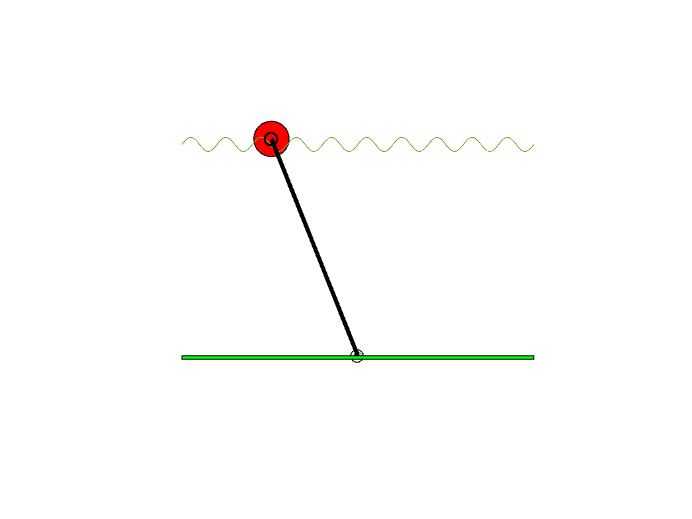


buoyvideo(buoypos, r, wavefunc, originalvals, N);